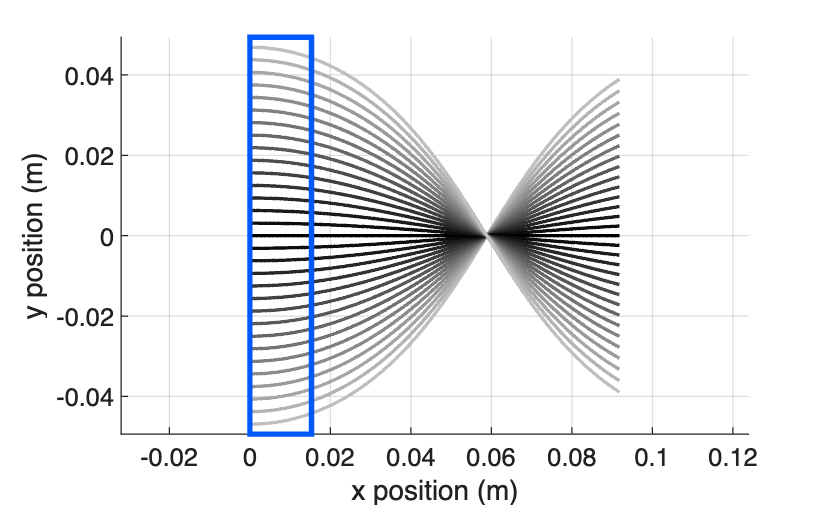

%Plot ray trajectories
figure;
hold on; grid on; axis equal;

N = length(y0);

for i = 1:N

    y = (1/alpha).*asinh(sinh(alpha*y0(i)).*cos(alpha*x));

    %Grayscale Gradient
    dist_from_centre = abs(y0(i)) / max(abs(y0));
    gray_value = 0.75 * dist_from_centre;
    ray_colour = [gray_value gray_value gray_value];

    plot(x, y, ...
        'Color', ray_colour, ...
        'LineWidth', 1.3);

end

%Lens outline in blue
rectangle('Position',[0 -h d 2*h], ...
    'EdgeColor',[0 0.35 1], ...
    'LineWidth',2);

xlabel('x position (m)');
ylabel('y position (m)');

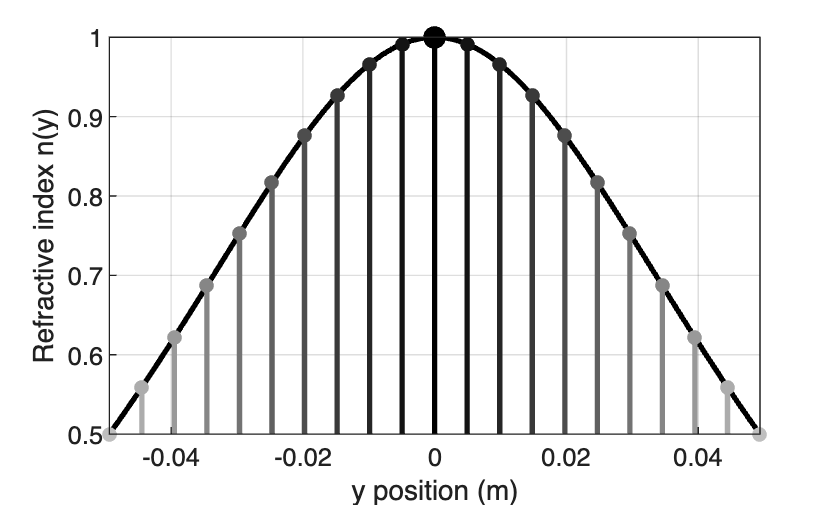



%plot refractive index profile
y_profile = linspace(-h,h,500);
n_profile = n0.*sech(alpha*y_profile);

figure;
hold on;
grid on;

%Continuous refractive index curve
plot(y_profile, n_profile, ...
    'k-', ...
    'LineWidth', 2);

Nrows = 21;
y_disc = linspace(-h,h,Nrows);
n_disc = n0.*sech(alpha*y_disc);

%Plot vertical discretised rows with a grey gradient
for i = 1:Nrows

    dist_from_centre = abs(y_disc(i)) / h;
    gray_value = 0.75 * dist_from_centre;
    row_colour = [gray_value gray_value gray_value];

    plot([y_disc(i) y_disc(i)], ...
         [0.5 n_disc(i)], ...
         '-', ...
         'Color', row_colour, ...
         'LineWidth', 2);

    plot(y_disc(i), n_disc(i), ...
         'o', ...
         'MarkerFaceColor', row_colour, ...
         'MarkerEdgeColor', row_colour, ...
         'MarkerSize', 5);
end

%Centre pointt
plot(0, n0, 'ko', ...
    'MarkerFaceColor','k', ...
    'MarkerSize', 8);

rectangle('Position',[-h 0.5 2*h n0-0.5]);

ylim([0.5 n0]);
xlim([-h h]);

xlabel('y position (m)');
ylabel('Refractive index n(y)');